# 地区ごとにMarkovレーティングを算出する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

tbl_results_tmp=tbl_results(tbl_results.SeasonStartYear==2018,:);
tbl_teams_tmp=tbl_teams(tbl_teams.SeasonStartYear==2018,:);

## Markov ratingの計算例(地区単位)

1地区のチームのみ抽出 

tmpAbb=tbl_teams_tmp.Abb(tbl_teams_tmp.Division=='Atlantic')

tmpAbb = 5×1 の categorical 配列
     BOS 
     BKN 
     NYK 
     PHI 
     TOR 


tmpTeams=tbl_teams_tmp.TeamName(tbl_teams_tmp.Division=='Atlantic')

tmpTeams = 5×1 の categorical 配列
     Boston Celtics 
     Brooklyn Nets 
     New York Knicks 
     Philadelphia 76ers 
     Toronto Raptors 


ind= (ismember( tbl_results_tmp.Home, tmpTeams) & ...
    ismember( tbl_results_tmp.Away, tmpTeams) & ...
    tbl_results_tmp.isRegular);
tbl_results_div=tbl_results_tmp(ind,:);

勝敗数およびそれを変換した遷移行列を計算する

V=zeros(size(tmpTeams,1));
S=zeros(size(tmpTeams,1));
for n1=1:size(tbl_results_div,1)
    homeNum= find(tbl_results_div.Home(n1) == tmpTeams);
    awayNum= find(tbl_results_div.Away(n1) == tmpTeams);
    if tbl_results_div.HomeScore(n1)>tbl_results_div.AwayScore(n1)
        V(homeNum, awayNum)=V(homeNum, awayNum)+1;
    else
        V(awayNum, homeNum)=V(awayNum, homeNum)+1;
    end
end
V

V =      0     2     3     3     2
     2     0     3     2     1
     1     1     0     0     0
     1     2     4     0     1
     2     3     4     3     0


for n1=1:size(V,2)
    S(:,n1)=V(:,n1)/sum(V(:,n1));
end
S

S =          0    0.2500    0.2143    0.3750    0.5000
    0.3333         0    0.2143    0.2500    0.2500
    0.1667    0.1250         0         0         0
    0.1667    0.2500    0.2857         0    0.2500
    0.3333    0.3750    0.2857    0.3750         0


初期ベクトルを設定したMarkov連鎖を計算してみる．

rng(1); %コメントアウトすると書籍と同じ図が得られる
r=rand(size(S,2),1);r=r/sum(r);
tmpR=r;
for k=1:10
    tmpR=S*tmpR;
    r=[r tmpR];
end
tmpR

tmpR =     0.2684
    0.2158
    0.0717
    0.1842
    0.2599


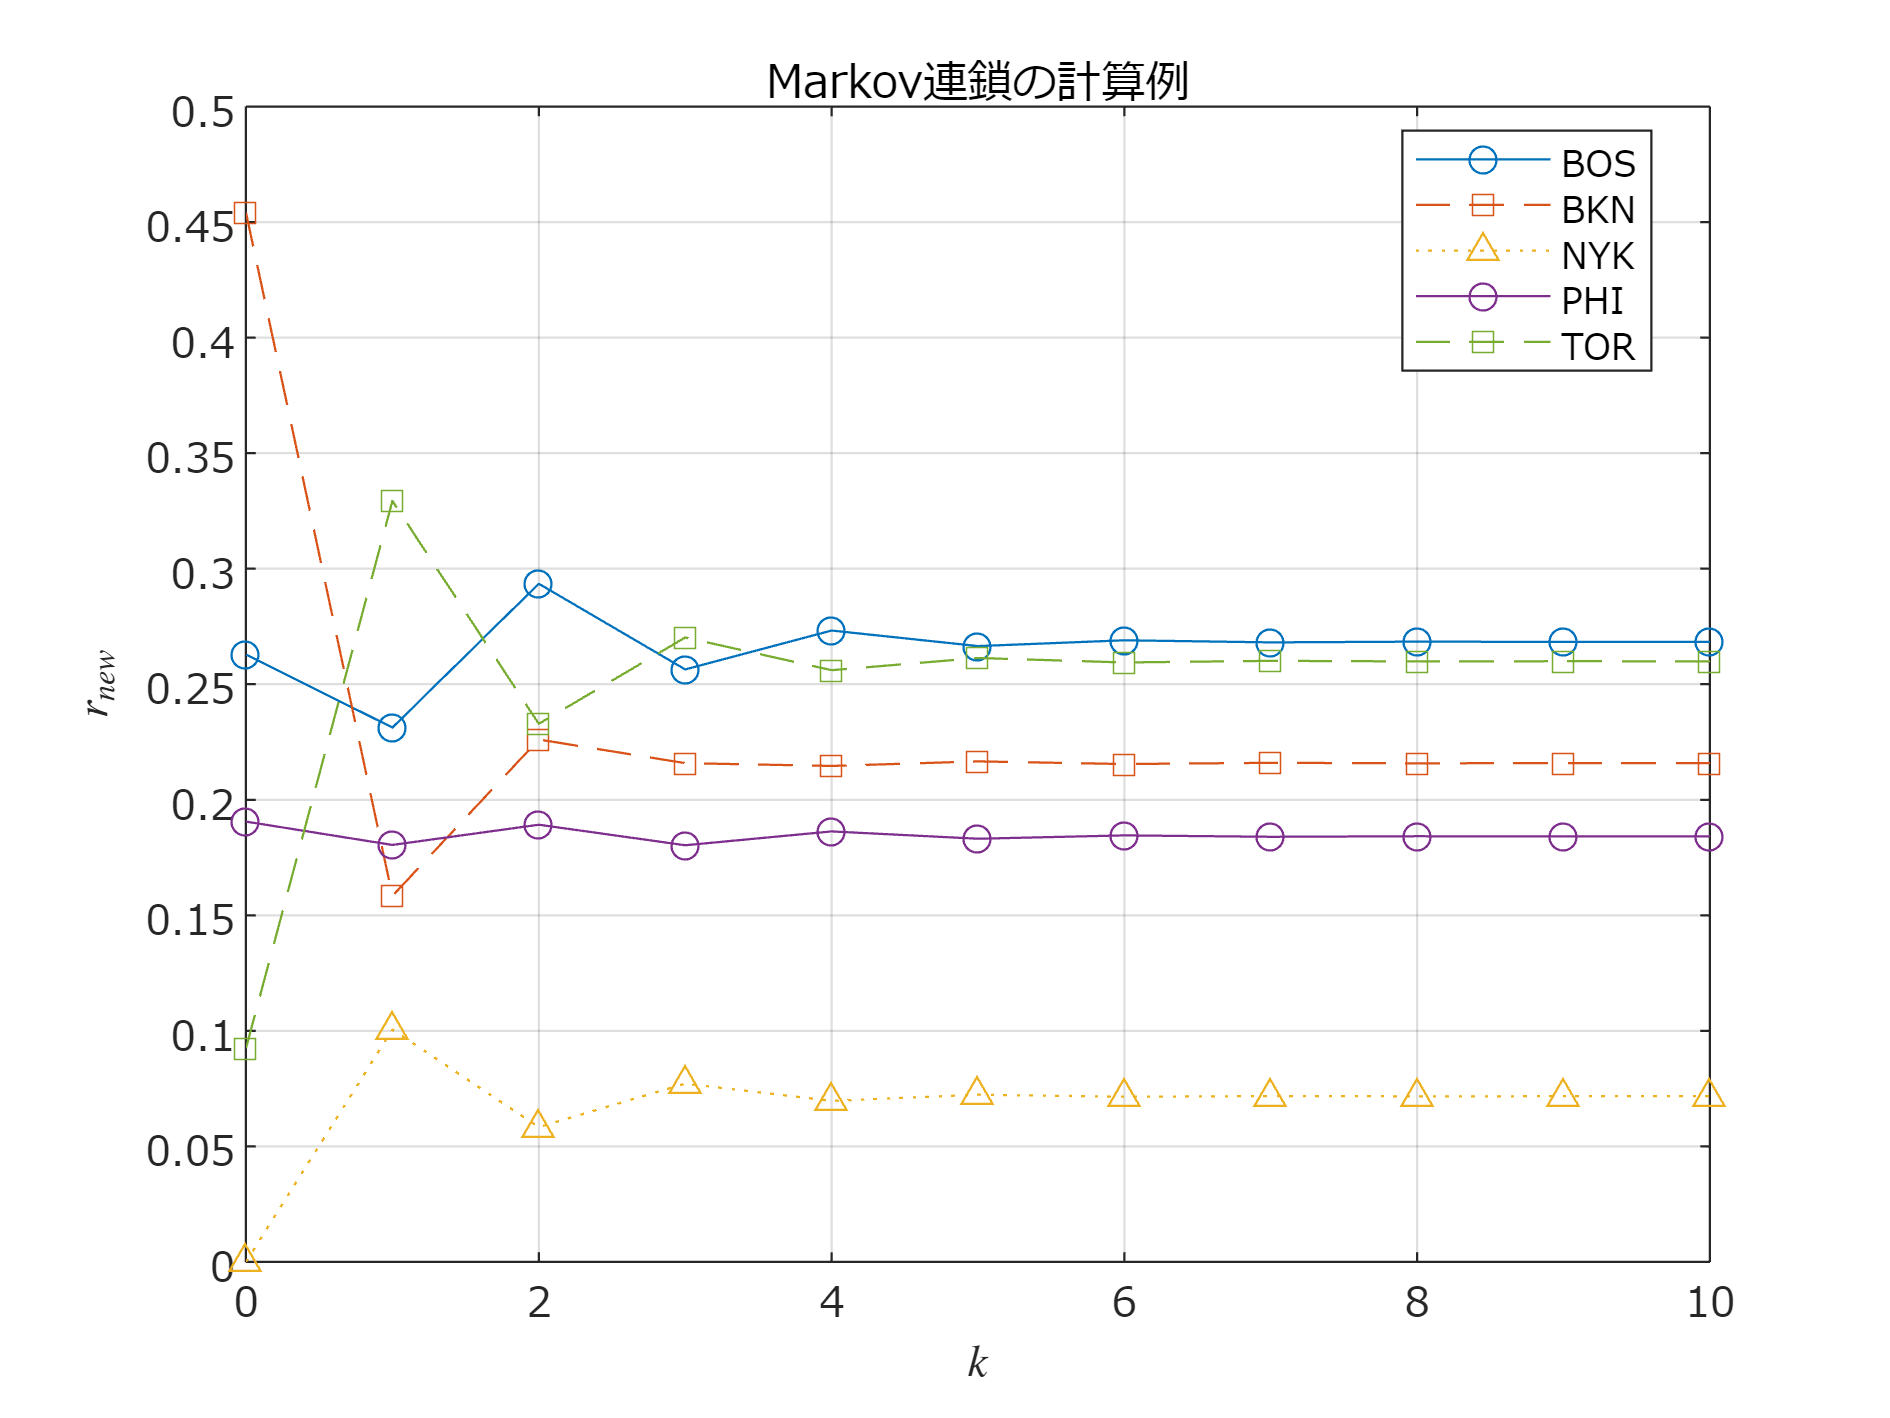

figure;
plot(0:10, r');
ax=gca;
mylinestyles = ["-o"; "--s"; ":^"];
ax.LineStyleOrder = mylinestyles;
ax.LineStyleCyclingMethod = "withcolor";
set(gca,'fontname','メイリオ');grid on;
xlabel('$k$','Interpreter','latex');ylabel('$r_{new}$','Interpreter','latex');
exportgraphics(gcf,'fig_MarkovSmallSample.pdf');
legend(string(tbl_teams_tmp.Abb(tbl_teams_tmp.Division=='Atlantic')),'location','best');
title('Markov連鎖の計算例')

Markovレーティングを算出する

b=0.85;
r=inv(eye(size(S))-b*S)*(1-b)*ones(size(tmpTeams))/size(tmpTeams,1)

r =     0.2584
    0.2129
    0.0892
    0.1871
    0.2524


## 図示

有向グラフとして図示する．頂点名をチーム略称とする．

nodeNames=string(tmpAbb)

nodeNames = 5×1 の string 配列
    "BOS"
    "BKN"
    "NYK"
    "PHI"
    "TOR"


辺(始点と終点の組)を重みとともに集計する．

EdgeTable=[];
w=[];
for n1=1:size(V,1)
    for n2=1:size(V,2)
        if V(n1,n2)>0
            EdgeTable=[EdgeTable;n2 n1];
           w=[w;S(n1,n2)];
        end
    end
end
EdgeTable=table(EdgeTable, 'VariableNames',{'EndNodes'})

EdgeTable = 18×1 table
    EndNodes
    ________

     2    1 
     3    1 
     4    1 
     5    1 
     1    2 
     3    2 
     4    2 
     5    2 
     1    3 
     2    3 
     1    4 
     2    4 
     3    4 
     5    4 
     1    5 
     2    5 


集計した辺をもつ有向グラフを作成する．

G=digraph(EdgeTable.EndNodes(:,1),EdgeTable.EndNodes(:,2),w);
figure;

カラーマップ(数値と色の対応)を設定．(お好みで)

colormap cool;

グラフを図示する．plot関数は無向・有向グラフを入力にできる．デフォルトの設定でかなりいい感じに描画してくれます．

ここでは以下を設定しています．

- 'Nodelabel'：頂点につける文字列をチームの略称とする

- 'Edgelabel'：辺につける文字列を数値の分数表記とする

- 'Arrowsize'：辺の矢印の大きさ

- 'MarkerSize'：頂点の丸印の大きさ

- 'NodeCData'：頂点の色の値．Markovレーティングと一致させている．

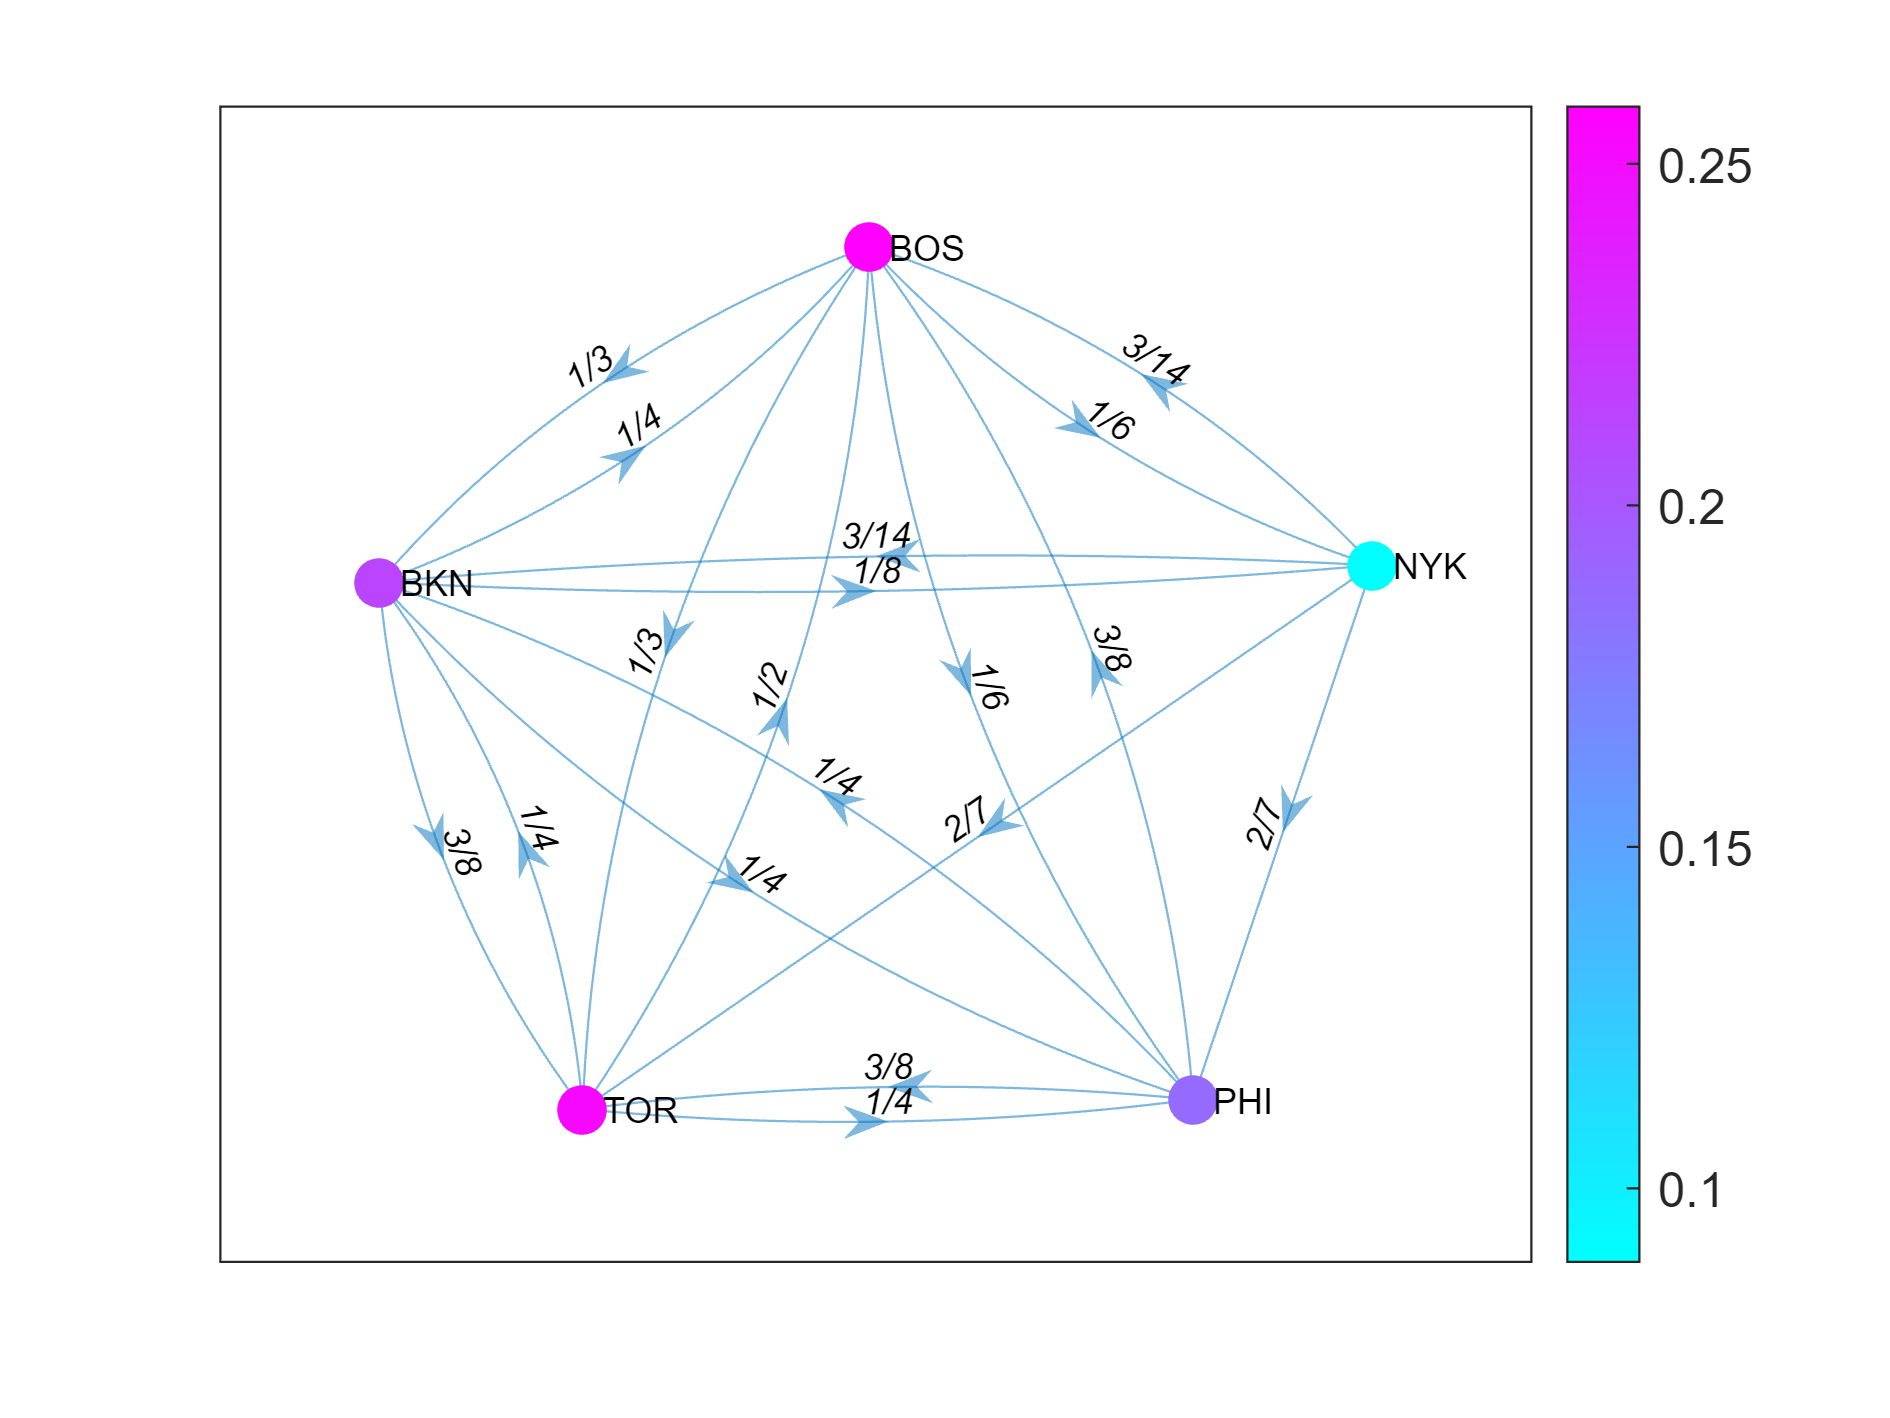

GPlotObj=  plot(G, 'NodeLabel',nodeNames,'EdgeLabel',string(sym(G.Edges.Weight)), ...
    'ArrowSize',10, 'MarkerSize',10,'NodeCData',r);
colorbar;
set(gca,'FontName','Arial','FontSize',12)
exportgraphics(gcf,'fig_MarkovSample.pdf')